# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'pdf';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING; %#ok<GVMIS> 
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\C_project\\ParkingMeterProject\\x64\\Release\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
--> Processing the test case #1: Straight Ticket Purchase...


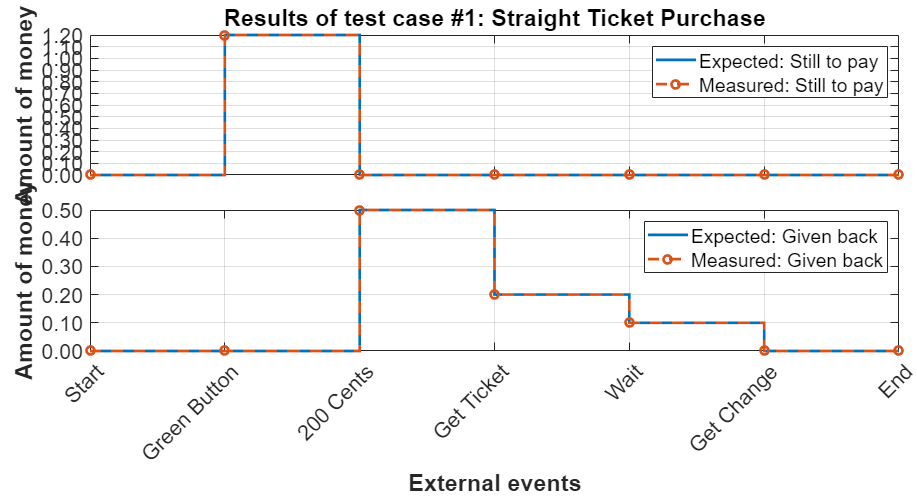


[Terse] Diagnostic logged (2022-07-10 18:50:26):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_5f30728d-4f74-40bf-80b7-504310398c6d.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_5f30728d-4f74-40bf-80b7-504310398c6d.png
--------------------------------------------------------------------------------
.--> Processing the test case #2: Biggest Change On Ticket Purchase...


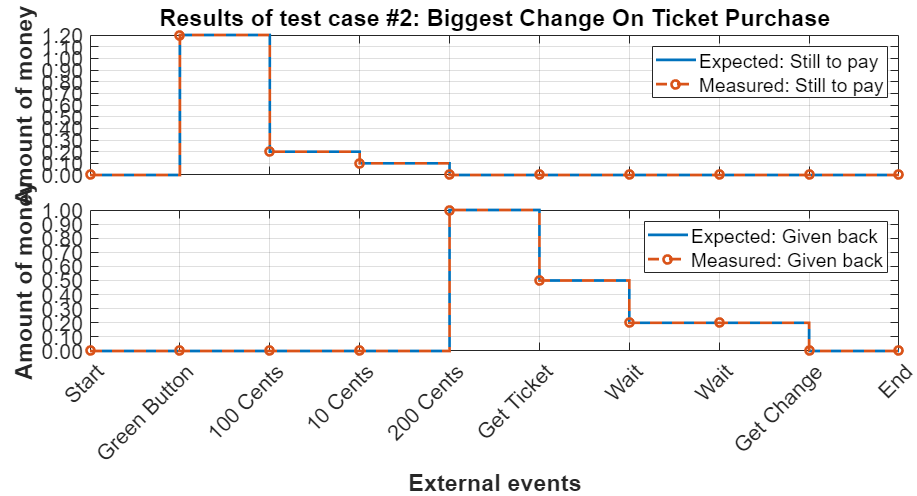


[Terse] Diagnostic logged (2022-07-10 18:50:50):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_5638f3e6-8976-4237-879c-484642629677.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_5638f3e6-8976-4237-879c-484642629677.png
--------------------------------------------------------------------------------
.--> Processing the test case #3: Cancel Ticket Purchase...


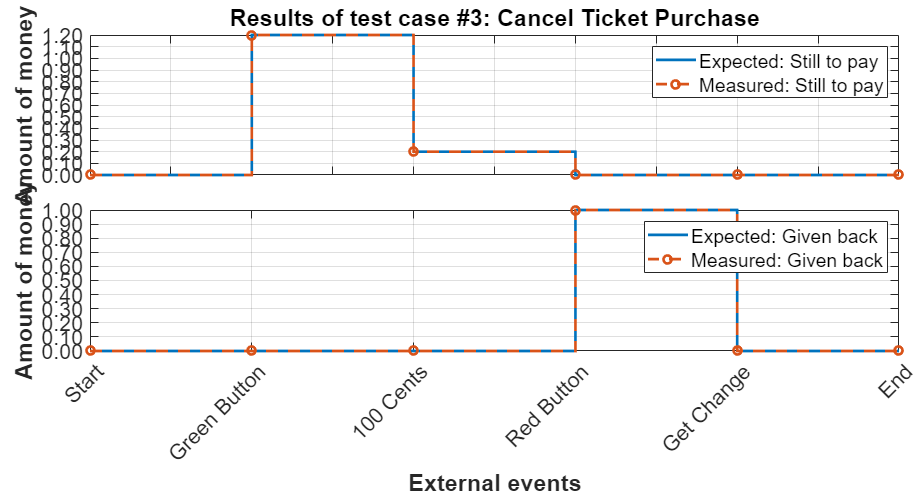


[Terse] Diagnostic logged (2022-07-10 18:51:08):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_3dbb35b4-b336-4640-ba95-8f4b17194f18.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_3dbb35b4-b336-4640-ba95-8f4b17194f18.png
--------------------------------------------------------------------------------
.--> Processing the test case #4: 50 Cents Incremental Ticket Purchase...


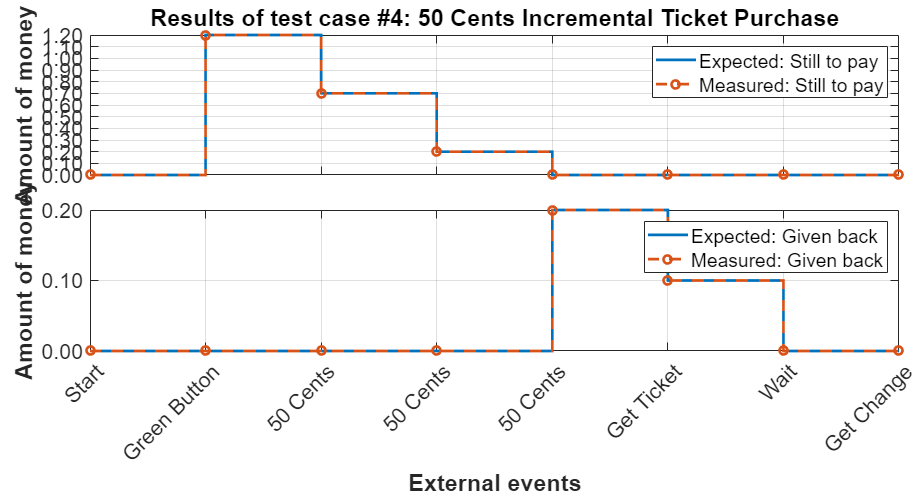


[Terse] Diagnostic logged (2022-07-10 18:51:47):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_ec8695fb-b51a-425e-bc64-01b417437d6a.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_ec8695fb-b51a-425e-bc64-01b417437d6a.png
--------------------------------------------------------------------------------
.--> Processing the test case #5: 20 Cents Incremental Ticket Purchase...


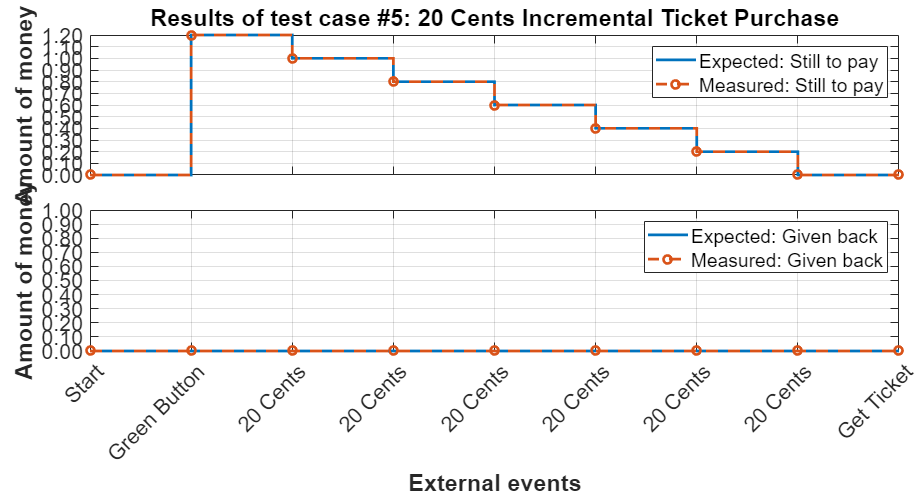


[Terse] Diagnostic logged (2022-07-10 18:52:16):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_6bab85eb-c814-4e99-8511-cc2564f9a9d8.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_6bab85eb-c814-4e99-8511-cc2564f9a9d8.png
--------------------------------------------------------------------------------
.--> Processing the test case #6: 10 Cents Incremental Ticket Purchase...


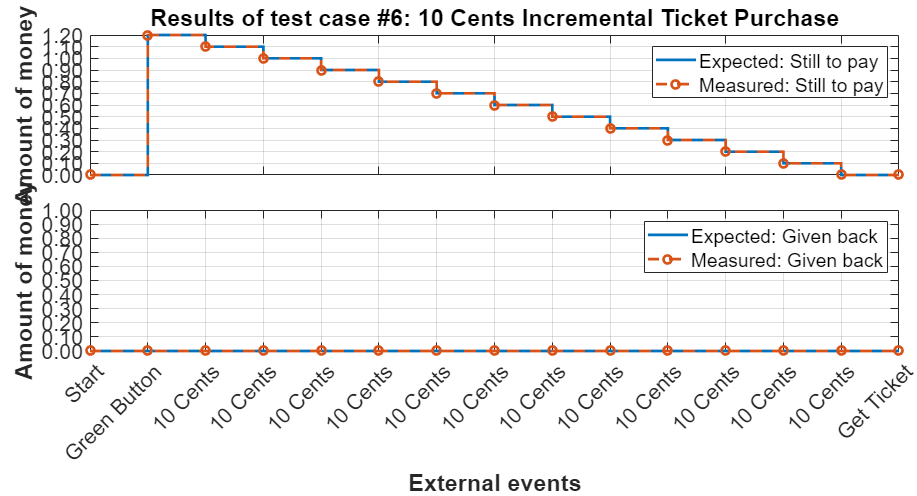


[Terse] Diagnostic logged (2022-07-10 18:52:55):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_bfe38f5a-4924-4e52-bb20-0a60d44389aa.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_bfe38f5a-4924-4e52-bb20-0a60d44389aa.png
--------------------------------------------------------------------------------
.--> Processing the test case #7: Fully Empty And Reload CashBox...


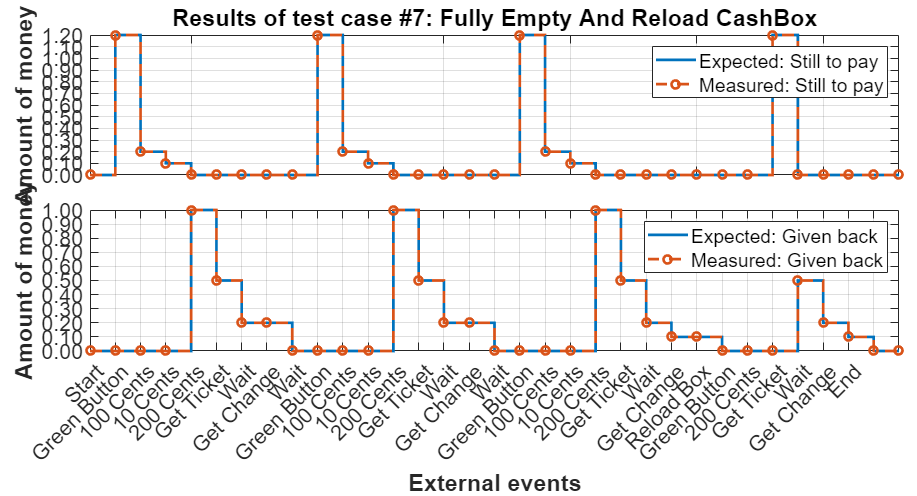


[Terse] Diagnostic logged (2022-07-10 18:53:54):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_a3f0b322-04da-49b3-aa24-d86204a26ec8.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_a3f0b322-04da-49b3-aa24-d86204a26ec8.png
--------------------------------------------------------------------------------
.--> Processing the test case #8: Switch Off The Low Level Application...


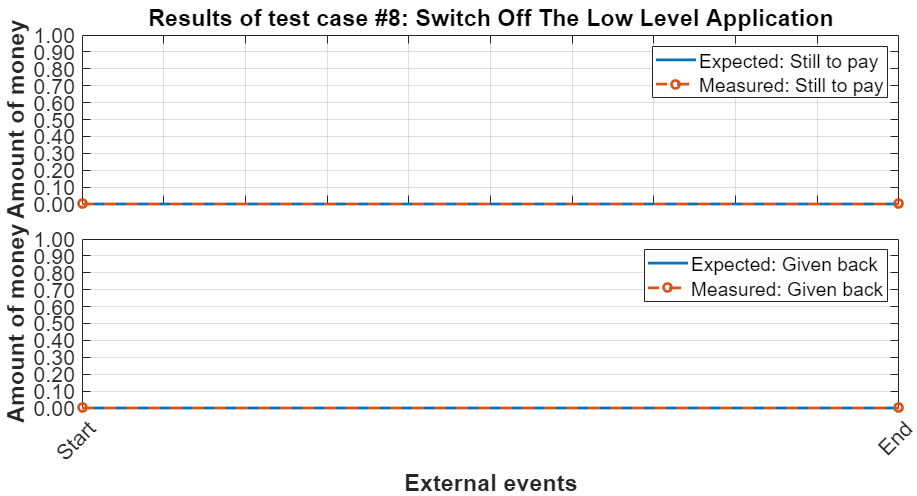


[Terse] Diagnostic logged (2022-07-10 18:54:07):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_b9e411f5-c4f6-4f46-96bd-b1434d91917b.fig
--> C:\Users\sebas\AppData\Local\Temp\87da19fc-2905-4f29-82af-b38614487088\Figure_b9e411f5-c4f6-4f46-96bd-b1434d91917b.png
--------------------------------------------------------------------------------
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.
    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\Parking_Meter\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp9f9231b2_e110_4406_8e24_a37869dee024\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                             Name                             Passed    Failed    Incomplete    Duration      Details   
    ______________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_StraightTicketPurchase'           }    true      false       false        24.816     {1×1 struct}
    {'TestApp/testCase_BiggestChangeOnTicketPurchase'    }    true      false       false        22.743     {1×1 struct}
    {'TestApp/testCase_CancelTicketPurchase'             }    true      false       false        32.575     {1×1 struct}
    {'TestApp/testCase_050CentsIncrementalTicketPurchase'}    true      false       false        24.011     {1×1 struct}
    {'TestApp/testCase_020CentsIncrementalTicketPurchase'}    true   